# Process python data

clear; clc; close;

% addpath("C:\Users\satur\.spyder-py3\proper orthogonal decomposition") %for local use
% %addpath(genpath("DMD")) %for local use
% addpath 'C:\Users\satur\OneDrive - University of Kansas\MATLAB\DMD' %for local use

## working bit


caseName = "DMD_combustorDataPressure";
%modeNumber = 0

%small test 1000 modes
% numberOfModes = 998;
% modeSize = 38523;
% timeDynamicSize = 998;

%for cluster use
numberOfModes = 70000-2; % actualy 38522 modes
modeSize = 38523;
timeDynamicSize = 70000-2; %TODO: find size programaticly

% for undersamped data thing

%modes = zeros(modeSize,numberOfModes+1);
contTimeEigVals = zeros(1,numberOfModes);

for modeNumber = 0:numberOfModes % starts with zero
    if mod(modeNumber,10) == 0 % on every tenth mode
        fprintf("mode: %d \n", modeNumber) % print mode number
    end
    % don't save modes or time dyn for memmory reasons
    try
        [contTimeEigVal, ~, ~] = getModeData(caseName,modeNumber); % FIXME? time dynamics are all the same! so we are not useing them.
        contTimeEigVals(modeNumber+1) = contTimeEigVal;
    catch ME
        %contTimeEigVals = contTimeEigVals(1:modeNumber-1); % truncate unnesseary zereos
        contTimeEigVals = contTimeEigVals(1:modeNumber); % truncate unnesseary zereos (this should include the last mode as well unlike the version above)
        %save(caseName+"_ContTimeEigVals","contTimeEigVals"); % saveing eig vals now (should not be nesseary as will happen after breaking out of while loop)
        disp(ME)
        disp("identifier: "+ME.identifier)
        disp("message: "+ME.message)
        break
    end
end

mode: 0 
mode: 10 
mode: 20 
mode: 30 
mode: 40 
mode: 50 
mode: 60 
mode: 70 
mode: 80 
mode: 90 
mode: 100 
mode: 110 
mode: 120 
mode: 130 
mode: 140 
mode: 150 
mode: 160 
mode: 170 
mode: 180 
mode: 190 
mode: 200 
mode: 210 
mode: 220 
mode: 230 
mode: 240 
mode: 250 
mode: 260 
mode: 270 
mode: 280 
mode: 290 
mode: 300 
mode: 310 
mode: 320 
mode: 330 
mode: 340 
mode: 350 
mode: 360 
mode: 370 
mode: 380 
mode: 390 
mode: 400 
mode: 410 
mode: 420 
mode: 430 
mode: 440 
mode: 450 
mode: 460 
mode: 470 
mode: 480 
mode: 490 
mode: 500 
mode: 510 
mode: 520 
mode: 530 
mode: 540 
mode: 550 
mode: 560 
mode: 570 
mode: 580 
mode: 590 
mode: 600 
mode: 610 
mode: 620 
mode: 630 
mode: 640 
mode: 650 
mode: 660 
mode: 670 
mode: 680 
mode: 690 
mode: 700 
mode: 710 
mode: 720 
mode: 730 
mode: 740 
mode: 750 
mode: 760 
mode: 770 
mode: 780 
mode: 790 
mode: 800 
mode: 810 
mode: 820 
mode: 830 
mode: 840 
mode: 850 
mode: 860 
mode: 870 
mode: 880 
mode: 890 
mode: 900 
mode: 910 

  MException with properties:

    identifier: 'MATLAB:FileIO:InvalidFid'
       message: 'Invalid file identifier. Use fopen to generate a valid file identifier.'
         cause: {}
         stack: [2×1 struct]
    Correction: []



identifier: MATLAB:FileIO:InvalidFid


message: Invalid file identifier. Use fopen to generate a valid file identifier.



save(caseName+"_ContTimeEigVals","contTimeEigVals"); %save eig als in case of error

initialState = str2num(cell2mat(importdata(caseName + "_initialState",','))); % read data from file as charater array segmented by ',' put it into a matrix

b = str2num(cell2mat(importdata(caseName + "_initialAmplitudes",',')));

## Visualization

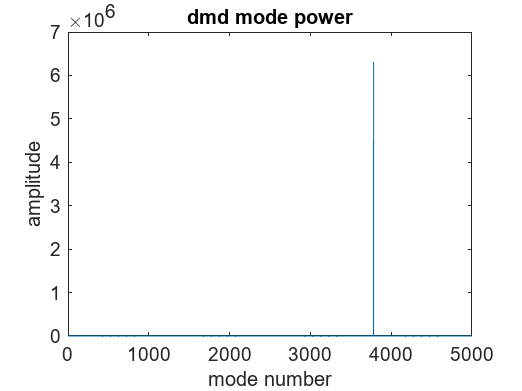

%mode power (scaled for grow/decay modes)
figure
plot(abs(b./contTimeEigVals))
title("dmd mode power");
xlabel("mode number");
ylabel("amplitude");
savefig("figure"+caseName+"_dmdmodepower"+".fig");
saveas(gcf,"figure"+caseName+"_dmdmodepower"+".jpg");

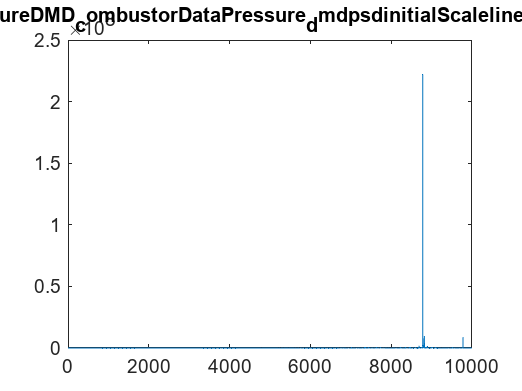


% Power Spectral Density

%not accounting for growth and decay modes.
figure
plot([log(abs(imag(contTimeEigVals/2/pi))),abs(b)])
title("figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".fig")
savefig("figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"initialScale"+"lines"+".jpg");

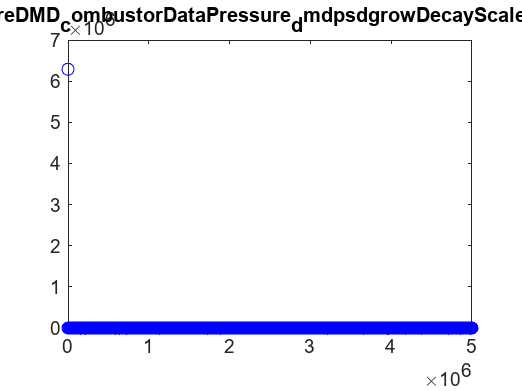


% Power Spectral Density scaled for growth and decay modes
figure
plot(abs(imag(contTimeEigVals/2/pi)),abs(b./contTimeEigVals),'bo') 
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"linear"+".jpg");

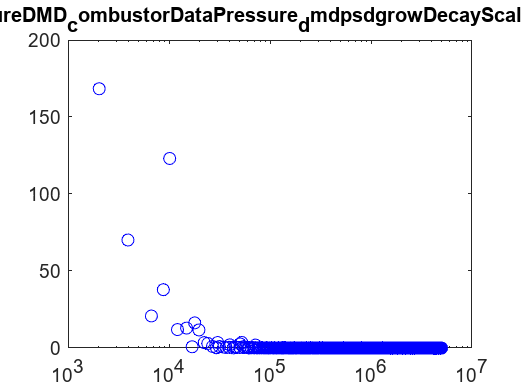


figure
semilogx(abs(imag(contTimeEigVals/2/pi)),abs(b./contTimeEigVals),'bo')
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"logx"+".jpg");

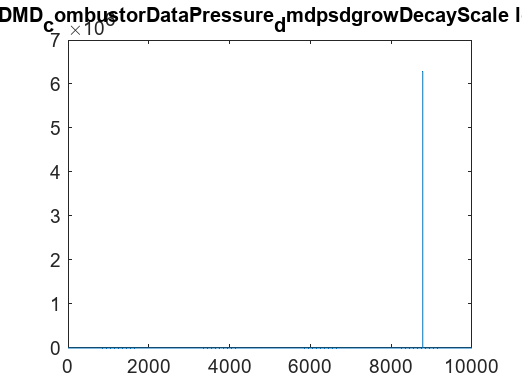


figure
plot([log(abs(imag(contTimeEigVals/2/pi))),abs(b./contTimeEigVals)]) %unsure if this is doing the correct thing 
title("figure"+caseName+"_dmdpsd"+"growDecayScale"+" log "+"lines")
savefig("figure"+caseName+"_dmdpsd"+"growDecayScale"+"lines"+".fig");
saveas(gcf,"figure"+caseName+"_dmdpsd"+"growDecayScale"+"lines"+".jpg");

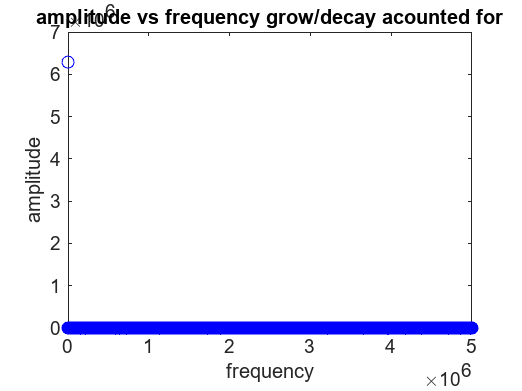


%these two are plotting the correct thing

%begin for debug
figure
plot((abs(imag(contTimeEigVals/2/pi))),abs(b./contTimeEigVals),'bo')
title("amplitude vs frequency grow/decay acounted for")
xlabel("frequency");
ylabel("amplitude");

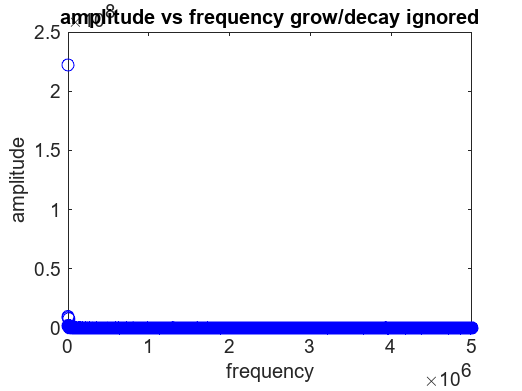


figure
plot((abs(imag(contTimeEigVals/2/pi))),abs(b),'bo')
title("amplitude vs frequency grow/decay ignored")
xlabel("frequency");
ylabel("amplitude");

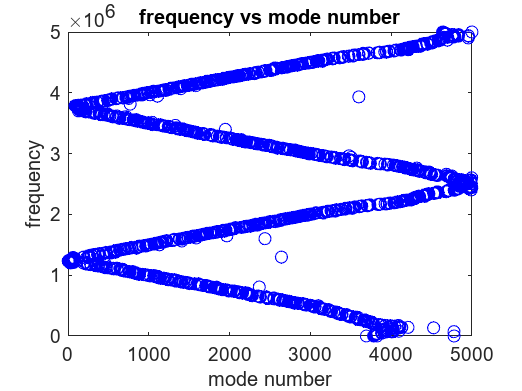

%end for debug


figure
plot((abs(imag(contTimeEigVals/2/pi))),'bo')
title("frequency vs mode number")
ylabel("frequency");
xlabel("mode number");
savefig("figure"+caseName+" frequency vs mode number"+".fig");
saveas(gcf,"figure"+caseName+" frequency vs mode number"+".jpg");

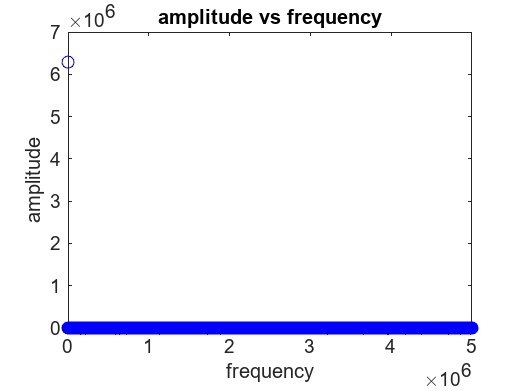



figure;plot((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("amplitude vs frequency")
ylabel("amplitude");
xlabel("frequency");
savefig("figure"+caseName+" amplitude vs frequency"+".fig");
saveas(gcf,"figure"+caseName+" amplitude vs frequency"+".jpg");

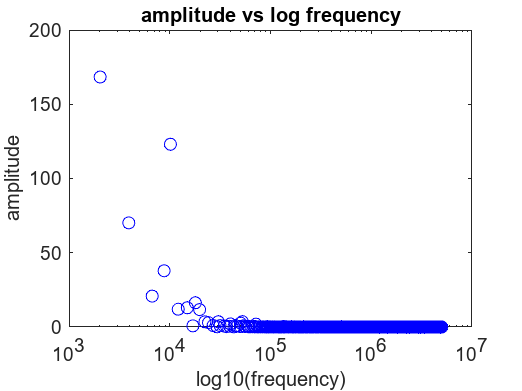


figure;semilogx((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("amplitude vs log frequency")
ylabel("amplitude");
xlabel("log10(frequency)");
savefig("figure"+caseName+" amplitude vs log frequency"+".fig");
saveas(gcf,"figure"+caseName+" amplitude vs log frequency"+".jpg");

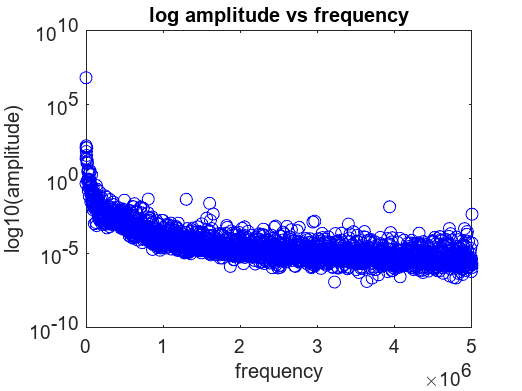


figure;semilogy((abs(imag(contTimeEigVals/2/pi))),abs(b./abs(contTimeEigVals)),'bo')
title("log amplitude vs frequency")
ylabel("log10(amplitude)");
xlabel("frequency");
savefig("figure"+caseName+" log amplitude vs frequency"+".fig");
saveas(gcf,"figure"+caseName+" log amplitude vs frequency"+".jpg");

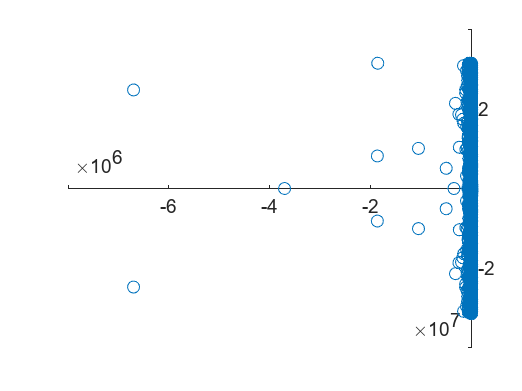

figure
scatter(real(contTimeEigVals),imag(contTimeEigVals))
ax = gca;
ax.YAxisLocation = 'origin';
ax.XAxisLocation = 'origin';
savefig("figure"+caseName+"_dmdsectrum"+".fig");
saveas(gcf,"figure"+caseName+"_dmdsectrum"+".jpg");